# **Surface de meshgrid en 3D**

Definimos el tamaño del espacio a utilizar

clear variables; clc;

m = 3;
dm = 0.5;

Creamos la malla, la utilizaremos como superficie de campo

[xx,yy] = meshgrid(-m:dm:m);

Ingresamos la función a graficar


$$\begin{array}{l}
f\left(x,y\right)=x^2 +y^2 \\
f\left(x,y\right)=x^2 -y^2 \\
f\left(x,y\right)=\textrm{xsin}\left(x\right)-\textrm{ycos}\left(y\right)
\end{array}$$


f = (xx.^2 + yy.^2 - 1).^3 - (xx.^2).*(yy.^3);

Hacemos el plot de la superficie y activamos la escala de colores

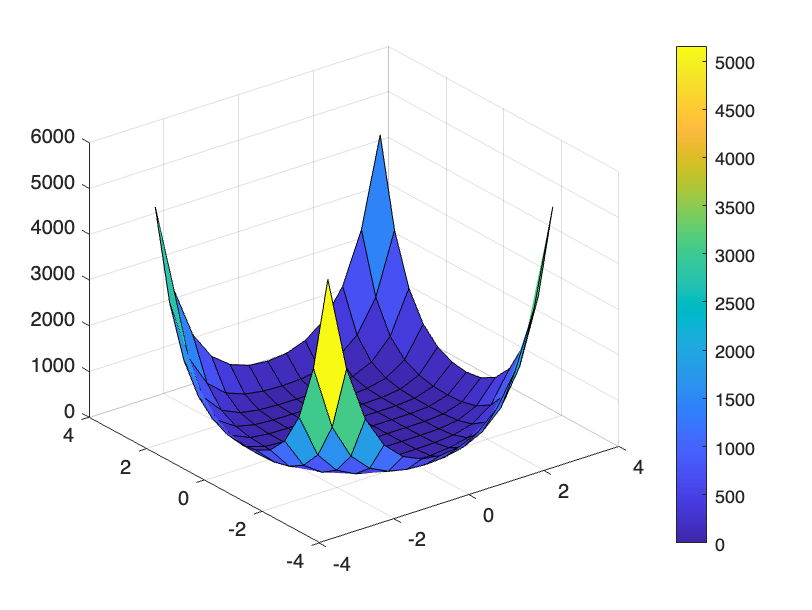

surf(xx,yy,f);
colorbar;